# **OrbitStateVector2ECR.m**

## **Purpose**

## **History**

## **Standard Gravitational Parameter**

The standard gravitational parameter $$\mu$$ of a celestial body is the product of the gravitational constant G and the mass M of the body. 

mu = 3.98618e14; % [m3/s2] Earth's geocentric gravitational constant

## **Get the Satellite TLE**

ID = 25544;
[TLE] = getSatelliteTLE(ID);

## **Convert to Orbital Elements**

[OE] = TLE2OrbitalElements(TLE);
fprintf(1,['Kepler Elements for satelliteID %d epoch %s:\n' ...
    '\ta [m] = %f\n\te = %f\n\ti [deg] = %f\n\tomega [deg] = %f\n' ...
    '\tOmega [deg] = %f\n\tM [deg] = %f\n'], floor(OE.satelliteID), ...
    datestr(OE.epoch),OE.a_km*1e3, OE.e, OE.i_deg, OE.omega_deg, ...
    OE.Omega_deg, OE.M_deg);

Kepler Elements for satelliteID 25544 epoch 20-Sep-2008 12:25:40:
	a [m] = 6731059.507584
	e = 0.000670
	i [deg] = 51.641600
	omega [deg] = 130.536000
	Omega [deg] = 247.462700
	M [deg] = 325.028800


a_m = OE.a_km*1e3;
e = OE.e;
M_deg = OE.M_deg;

%{
OE.satelliteID = 'ISS';
a_m = 6780663.07;
e = 0.0011495;
OE.a_km = a_m*1e-3;
OE.e = e;
OE.i_deg = 51.52894;
OE.omega_deg = 38.42846;
OE.Omega_deg = 341.20455;
OE.M_deg = 191.97036;
M_deg = 191.97036;
OE.epoch = datenum(2015,1,44,12,0,0);
fprintf(1,['Kepler Elements for satelliteID %d epoch %s:\n' ...
    '\ta [m] = %f\n\te = %f\n\ti [deg] = %f\n\tomega [deg] = %f\n' ...
    '\tOmega [deg] = %f\n\tM [deg] = %f\n'], floor(OE.satelliteID), ...
    datestr(OE.epoch),OE.a_km*1e3, OE.e, OE.i_deg, OE.omega_deg, ...
    OE.Omega_deg, OE.M_deg);
%}

## **Orbital Plane Coordinates**

n_rad_per_s = sqrt(mu/a_m^3);  % [rad/s] mean motion
n_deg_per_s = rad2deg(n_rad_per_s); % [deg/s] mean motion
M_rad = deg2rad(M_deg);
E_rad = M_rad; 
dE = 99999;
eps = 1e-6; % [rad] control precision of Newton's method solution
while (abs(dE) > eps)
    dE = (E_rad - e * sin(E_rad) - M_rad)/(1 - e * cos(E_rad));
    E_rad = E_rad -  dE;
end
p_m = a_m*(cos(E_rad) - e);
q_m = a_m*sqrt(1 - e^2)*sin(E_rad);

dMdt_rad_per_s = n_rad_per_s;
dEdt_rad_per_s = dMdt_rad_per_s/(1 - e*cos(E_rad));
dpdt_m_per_s = -a_m*sin(E_rad)*dEdt_rad_per_s;
dqdt_m_per_s = a_m*cos(E_rad)*dEdt_rad_per_s*sqrt(1 - e^2);
E_deg_epoch = rad2deg(E_rad);

## **Rotate To ECI**

Rz_Omega = [ ...
    [cosd(OE.Omega_deg) sind(OE.Omega_deg) 0]; ...
    [-sind(OE.Omega_deg) cosd(OE.Omega_deg) 0]; ...
    [0 0 1]];
Rx_i = [ ...
    [1 0 0]; ...
    [0 cosd(OE.i_deg) sind(OE.i_deg)]; ...
    [0 -sind(OE.i_deg) cosd(OE.i_deg)]];
Rz_omega = [ ...
    [cosd(OE.omega_deg) sind(OE.omega_deg) 0]; ...
    [-sind(OE.omega_deg) cosd(OE.omega_deg) 0]; ...
    [0 0 1]];

% time of epoch
[Year,Month,Day,H,M,S] = datevec(OE.epoch);
HourUTC = H + M/60.0 + S/3600.0;
jd = juliandate(Year,Month,Day,HourUTC,0,0);
jd0 = juliandate(Year,Month,Day,0,0,0);
% form time in Julian centuries from J2000
T = (jd - 2451545.0d0)./36525.0d0;
% D0 = (jd0 - 2451545.0d0);
% % [deg] GMST = Sidereal Time at Greenwich
% GMST = 6.697374558 + 0.06570982441908*D0 + 1.00273790935*HourUTC + 0.000026*T^2;
% % [deg] Sidereal Time
% ST_deg = 100.46061837 + 36000.770053608*T + 0.000387933*T^2 - T^3/38710000;
% GST_deg = ST_deg + 1.00273790935*HourUTC*15;
% %LST_deg = GST_deg - ObsLongitude_degW;

Theta_deg = 100.460618375 + 36000.770053608336*T + 0.0003879333*T^2 + 15*H + M/4 + mod(S/240,360);

Rz_hour = [ ...
    [cosd(Theta_deg) sind(Theta_deg) 0]; ...
    [-sind(Theta_deg) cosd(Theta_deg) 0]; ...
    [0 0 1]];

% position of satellite at epoch in the orbit pq plane
r_pq = [p_m q_m 0]';
% position of satellite at epoch in ECI coordinates

omega_deg = OE.omega_deg;
Omega_deg = OE.Omega_deg;
i_deg = OE.i_deg;

r_ECI = inv(Rz_Omega)*inv(Rx_i)*inv(Rz_omega)*r_pq;
%{
   % ways to get the ECI values
   px = cosd(omega_deg)*cosd(Omega_deg) - sind(omega_deg)*cosd(i_deg)*sind(Omega_deg);
   py = cosd(omega_deg)*sind(Omega_deg) + sind(omega_deg)*cosd(i_deg)*cosd(Omega_deg);
   pz = sind(omega_deg)*sind(i_deg);

   qx = -sind(omega_deg)*cosd(Omega_deg) - cosd(omega_deg)*cosd(i_deg)*sind(Omega_deg);
   qy = -sind(omega_deg)*sind(Omega_deg) + cosd(omega_deg)*cosd(i_deg)*cosd(Omega_deg);
   qz = cosd(omega_deg)*sind(i_deg);

   wx = sind(i_deg)*cosd(omega_deg);
   wy = -sind(i_deg)*sind(Omega_deg);
   wz = cosd(i_deg);

   r_ECI = [(p_m*px+q_m*qx) (p_m*py+q_m*qy) (p_m*pz+q_m*qz)];
%}

r_LLA = eci2lla(r_ECI',datevec(datenum(Year, Month, Day, H, M, S)),'IAU-2000/2006');
%{
  % another way to get the ECR values - if you want cartesian 
  r_ECR = Rz_hour*r_ECI;
  r_LLA = ecef2lla(r_ECR');
%}

Evals = 0:1:360.0; % [deg] values of the eccentric anomaly around orbit 
Orbit_p = a_m*(cosd(Evals)-e); % [m] orbit positions
Orbit_q = a_m*sqrt(1 - e^2)*sind(Evals); % [m] orbit positions
deltaT_s = ((Evals-E_deg_epoch) - e*sind(Evals-E_deg_epoch))/n_deg_per_s; % [s] time since epoch along orbit
% r_ECR_orbit = Rz_hour*r_ECI_orbit';
% r_LLA_orbit = ecef2lla(r_ECR_orbit');
% only due one at a time... <sigh>
Orbit_ECI = zeros(numel(deltaT_s),3);
Orbit_LLA = zeros(numel(deltaT_s),3);
for ipt = 1:size(Orbit_ECI,1)
    r_pq = [Orbit_p(ipt) Orbit_q(ipt) 0]';
    tmp = inv(Rz_Omega)*inv(Rx_i)*inv(Rz_omega)*r_pq; %[Rz_Omega*Rx_i*Rz_omega*r_pq]';
    Orbit_ECI(ipt,:) = tmp';
    lla = eci2lla(Orbit_ECI(ipt,:),datevec(datenum(Year, Month, Day, H, M, S+deltaT_s(ipt))),'IAU-2000/2006');
    Orbit_LLA(ipt,:) = lla;
end

## **Plot Cartesian Coordinates**

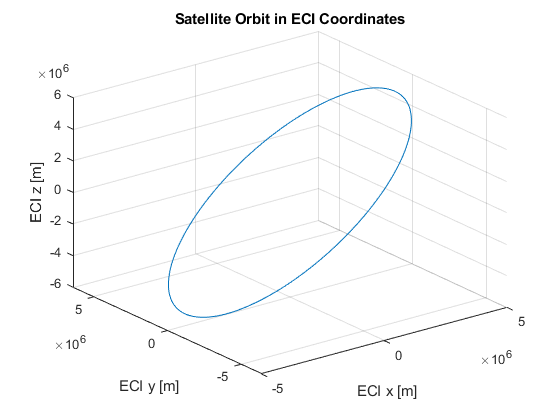

figure('color','white');
plot3(Orbit_ECI(:,1),Orbit_ECI(:,2),Orbit_ECI(:,3))
xlabel('ECI x [m]');
ylabel('ECI y [m]');
zlabel('ECI z [m]');
title('Satellite Orbit in ECI Coordinates');
grid on

## **Plot Map**

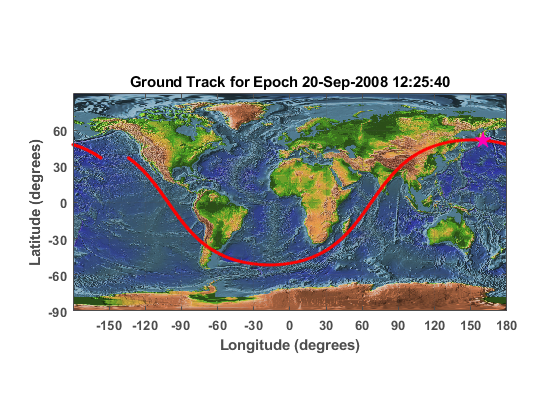

figure('color','white');
earth = imread('ear0xuu2.jpg');
lv= size(earth,1);
lh= size(earth,2);
lats =  (1:lv)*180/lv - 90;
lons =  (1:lh)*360/lh - 180;
image(lons, -lats, earth)
hold on;
set(gca,'ydir','normal');
grid on
plot(Orbit_LLA(:,2),Orbit_LLA(:,1),'.r');
plot(r_LLA(2),r_LLA(1),'p','MarkerFaceColor',[1 0 0.7],'MarkerEdgeColor','none','Markersize',14);
set(gca,'XTick',-180:30:180);
set(gca,'YTick',-90:30:90);
set(gca,'Xcolor',0.3*ones(1,3));
set(gca,'Ycolor',0.3*ones(1,3));
title(['Ground Track for Epoch ' datestr(OE.epoch)])
xlabel('Longitude (degrees)')
ylabel('Latitude (degrees)')
axis equal
axis tight
set(gca,'fontweight','bold');